# E6

Morfologia multinivell

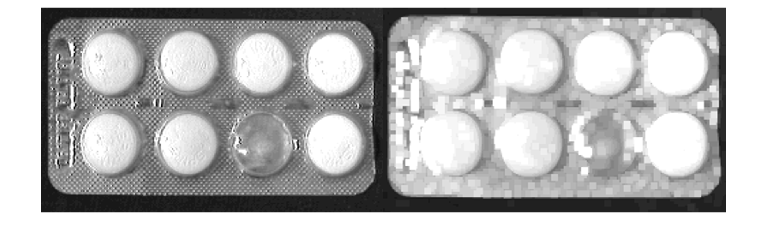

I = imread('astablet.tif');
SE = ones(5, 5);
ID = imdilate(I, SE);
montage({I, ID});

[f, c] = size(I);

mirem què ha passat

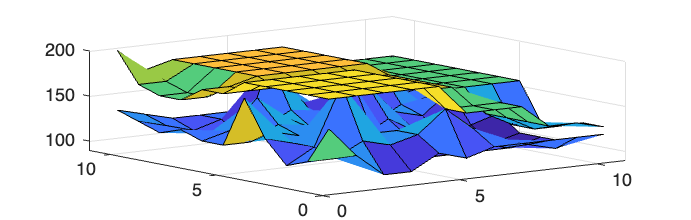

ICrop = I(floor(f/2)-5:floor(f/2)+5, floor(c/2)-5:floor(c/2)+5);
IDCrop = ID(floor(f/2)-5:floor(f/2)+5, floor(c/2)-5:floor(c/2)+5);

surf(ICrop);
hold on
surf(IDCrop);
hold off

dilate = ? max dels seus veïns

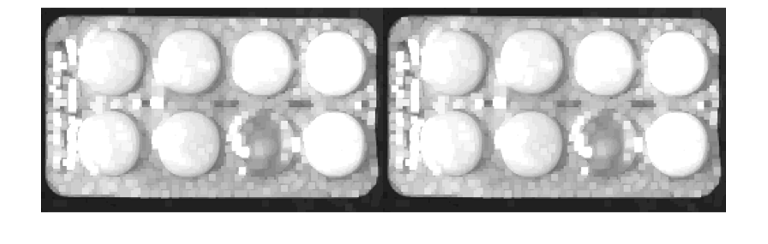

ID2 = colfilt(I, [5 5], "sliding", @max);
montage({ID, ID2});

erode 

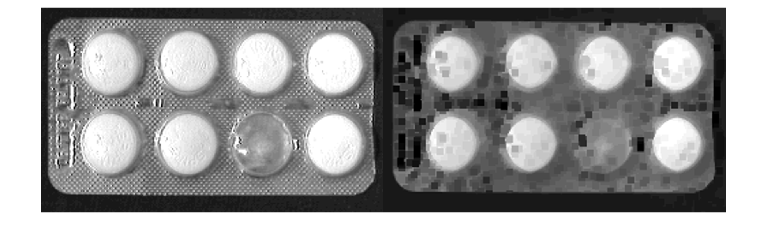

SE = ones(5, 5);
IE = imerode(I, SE);
montage({I, IE});

erode = ? min dels seus veïns

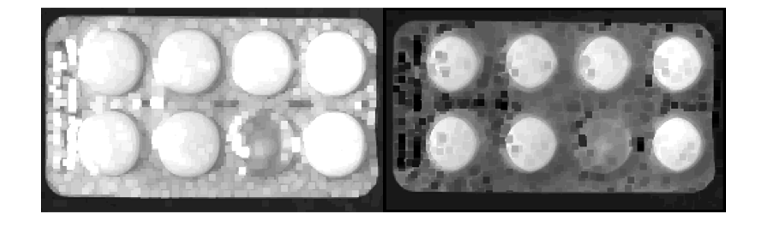

IE2 = colfilt(I, [5 5], "sliding", @min);
montage({ID, IE2});

open

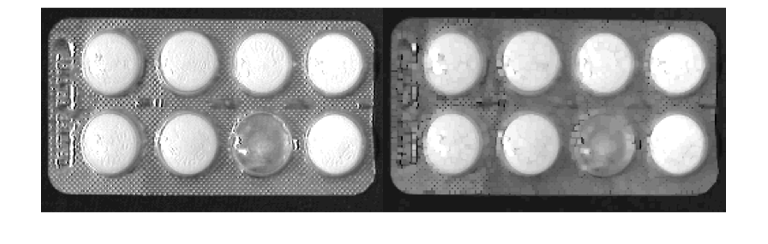

SE = ones(3, 3);
IO = imopen(I,SE);
montage({I, IO});

close

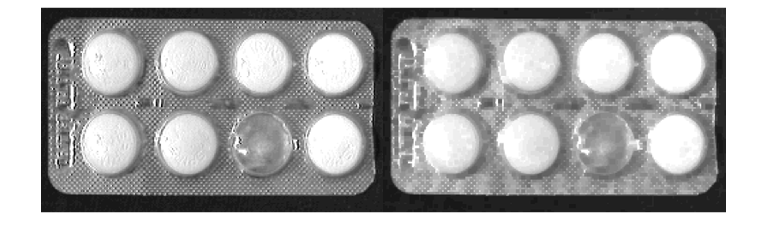

SE = ones(3, 3);
IC = imclose(I, SE);
montage({I, IC});

filtre openclose

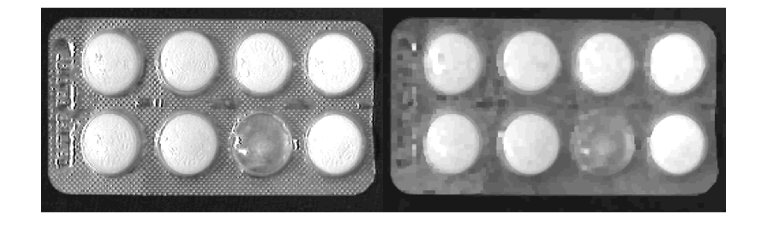

IOC = imclose(IO, SE);
montage({I, IOC});

residus

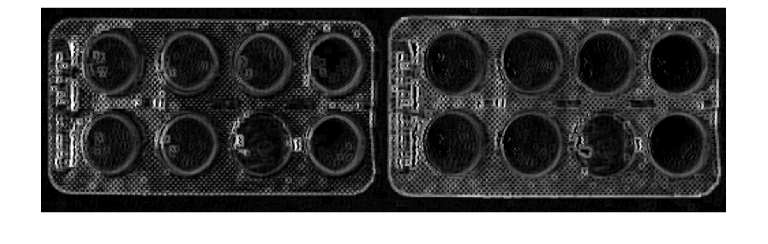

RI = I - IE; % interns
RE = ID - I; % externs
L = double(RE) - double(RI); % laplacià
montage({RI, RE});

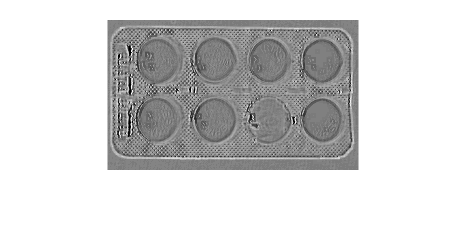

imshow(L, []);

Top hat i bottom hat

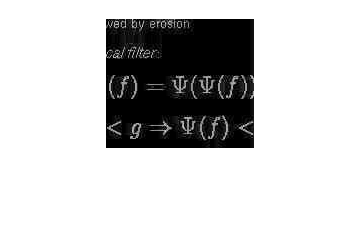

I = imread('nshadow.tif');
SE = ones(10, 10);
IO = imopen(I,SE);
IC = imclose(I,SE);
% top hat
TH = I - IO;
imshow(TH, []);

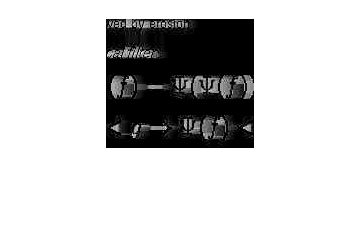

% bottom hat
BH = IC - I;
imshow(BH, []);

Reconstrucció a partir d'un punt 

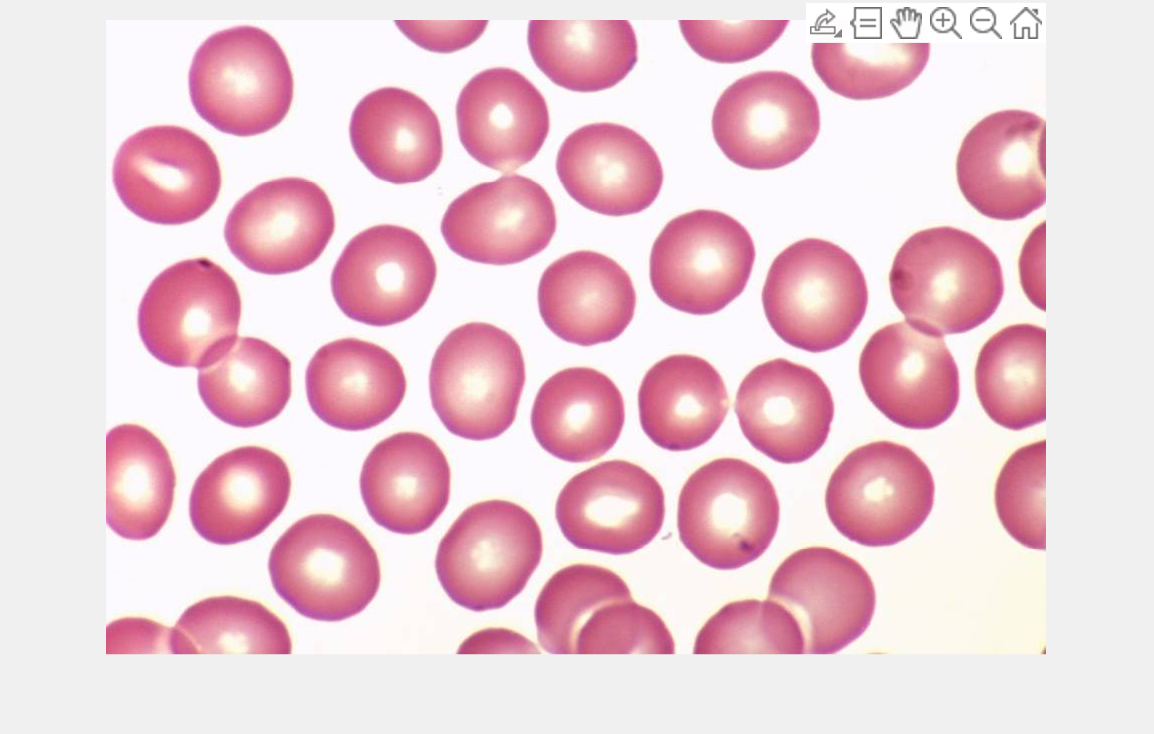

RGB = imread('normal-blood1.jpg');
I = rgb2gray(RGB);
imshow(RGB);
[x,y] = getpts;

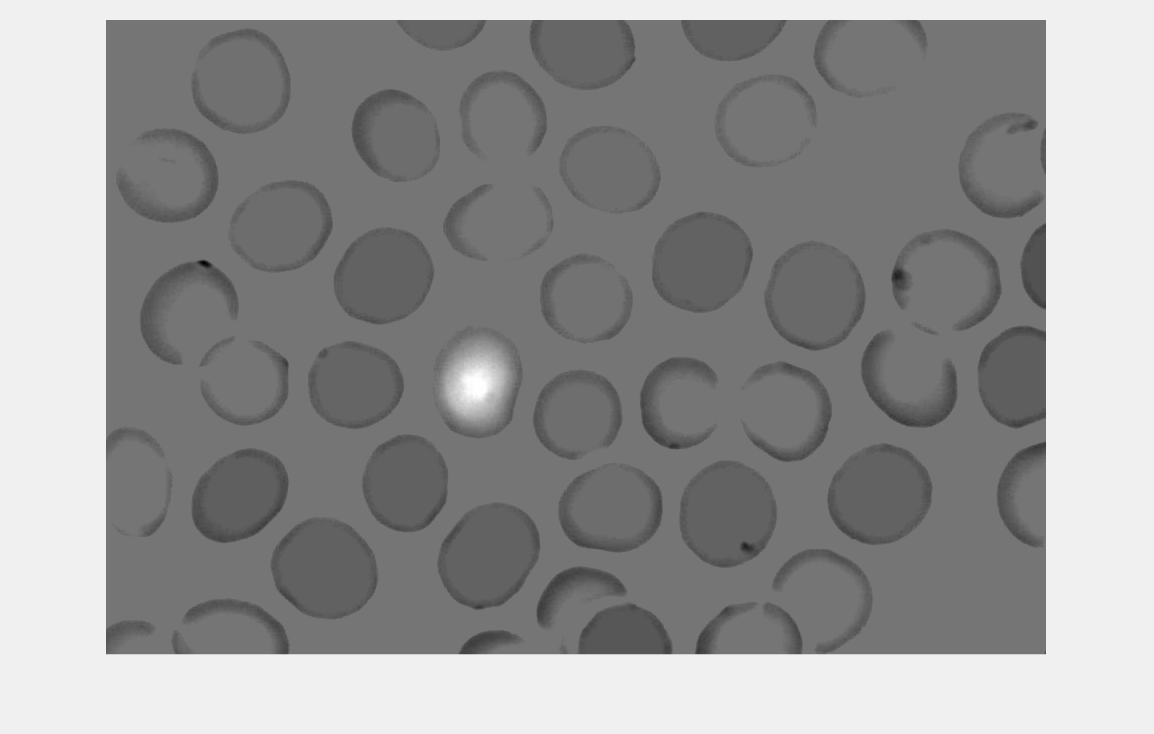

[f, c] = size(I);

MARK = uint8(zeros([f,c]));
MARK(uint16(y),uint16(x)) = 255;

REC = imreconstruct(MARK,I);
imshow(REC,[]);

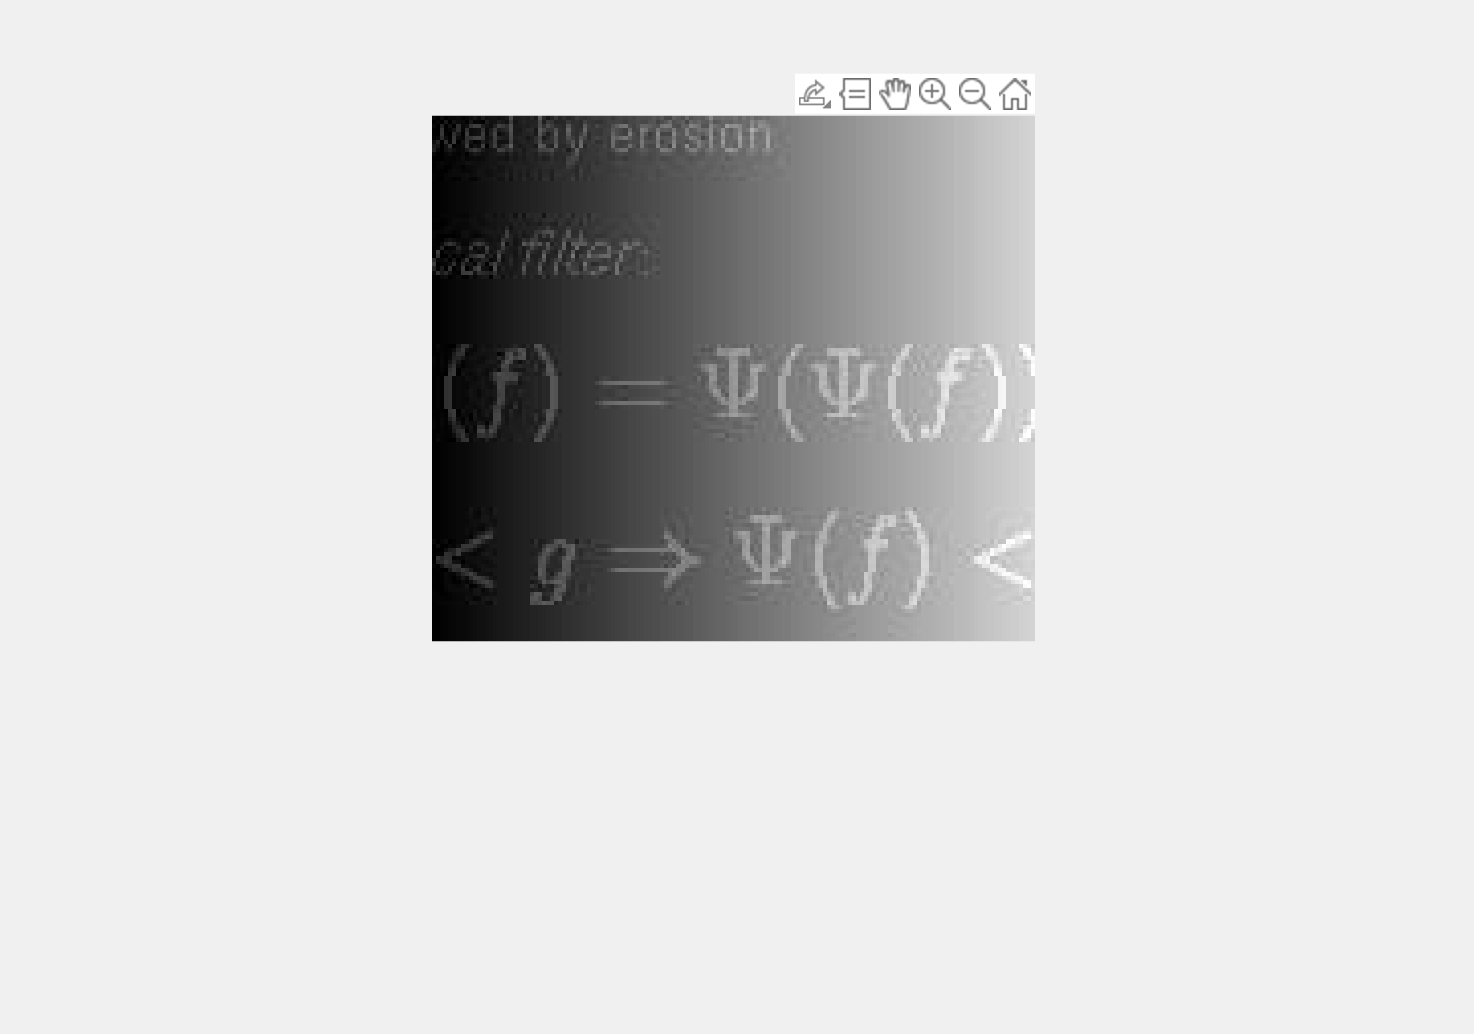

I = imread('nshadow.tif');
imshow(I);
[x,y] = getpts;

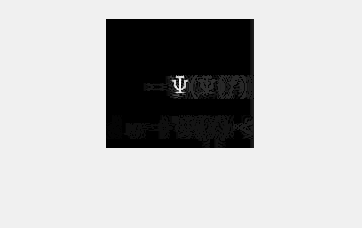

[f, c] = size(I);

MARK = uint8(zeros([f,c]));
MARK(uint16(y),uint16(x)) = 255;

REC = imreconstruct(MARK,TH);
imshow(REC,[]);

màxims i mínims regionals

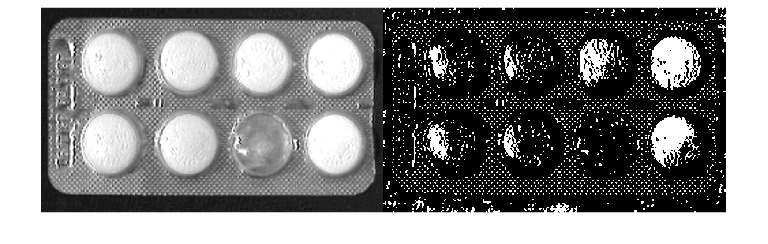

I = imread('astablet.tif');
MR = imregionalmax(I);
montage({I,MR});

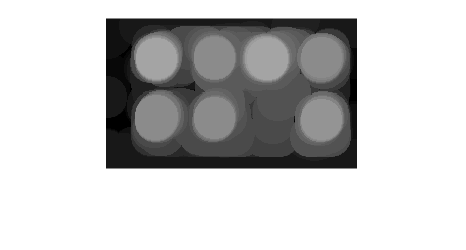

% masses maxims regionals

ES = fspecial("disk",20) > 0; % la mida del que estem buscant (mida de la pastilla)
IO = imopen(I,ES);
imshow(IO);

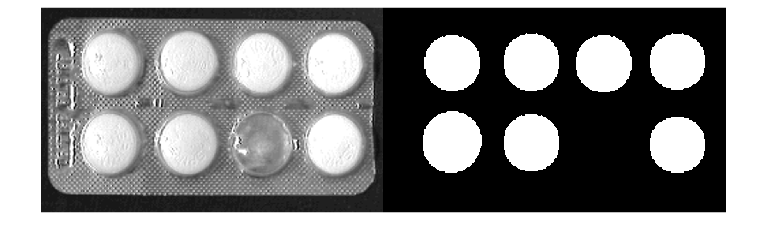

MRO = imregionalmax(IO);
montage({I, MRO});

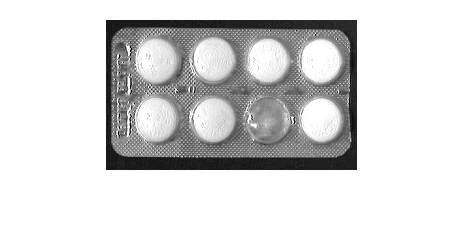


IM = I;
IM(not(MR)) = 0;
REC = imreconstruct(IM,I);
imshow(REC,[]);

Exercici: realitzar un plot granulometric

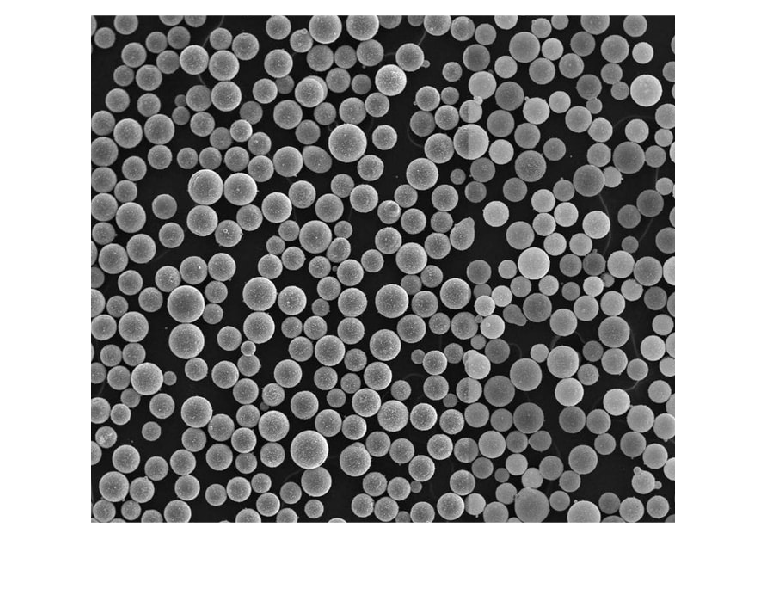

RGB = imread("granulometria.png");
I = rgb2gray(RGB);
imshow(I);

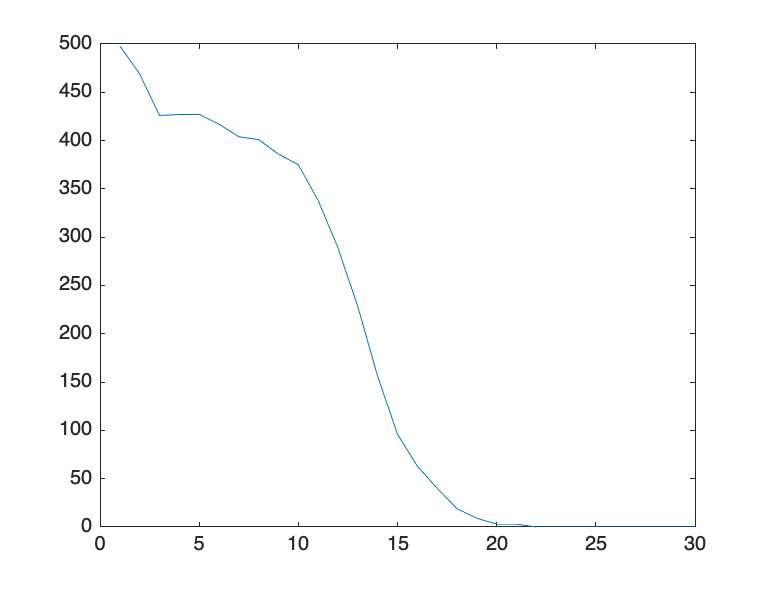


for i = 1:30
    ES = fspecial("disk", i) > 0;
    IO = imopen(I,ES);
    t = otsuthresh(imhist(IO));
    t = max(64, t*255);
    BW = IO > t;
    if (sum(sum(BW)) > 0)
        BWUE = bwulterode(BW);
        CC = bwconncomp(BWUE);
        A(i) = CC.NumObjects;
    else
        A(i) = 0;
    end
end

plot(A)